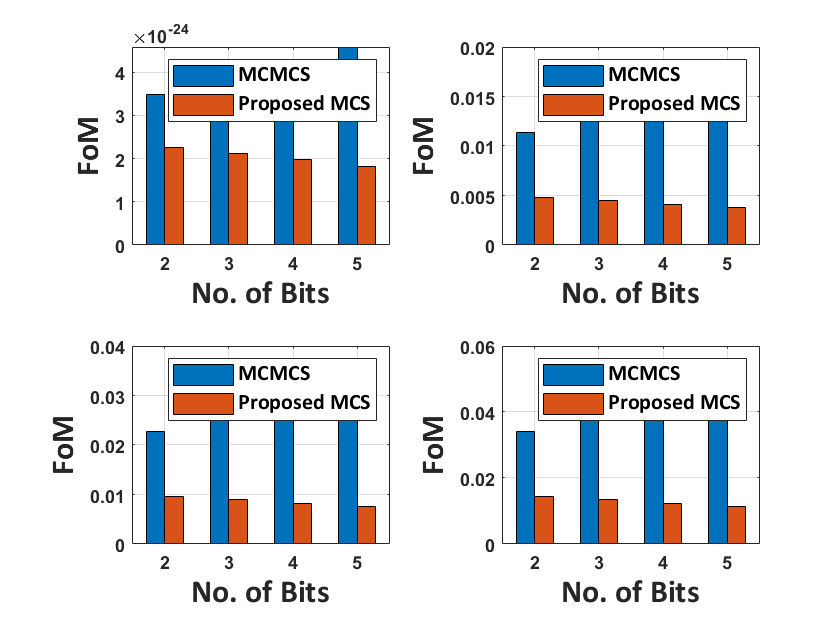


clc
close all
clear
load FoM_de.mat FoM_de
load FoM_mc.mat FoM_mc
load FoM_nm.mat FoM_nm
load FoM_denm.mat FoM_denm
figure(1)
for iap=1:4
    
    subplot(220+iap)
    Bit=2:5;
    %  bar1(1:4,3) = reshape(FoM_de(iap,Bit,1),[4,1]);
    % bar1(1:4,7) = reshape(FoM_de(iap,Bit,2),[4,1]);
    %  bar1(1:4,2) = reshape(FoM_nm(iap,Bit,1),[4,1]);
    % bar1(1:4,6) = reshape(FoM_nm(iap,Bit,2),[4,1]);
    p = polyfit(Bit, reshape(FoM_mc(iap,Bit,1),[4,1])', 1); % 进行二次拟合，获取多项式系数
    yy_mc = polyval(p, Bit); % 计算拟合曲线的纵坐标
    bar1(1:4,1) = yy_mc;%reshape(FoM_mc(iap,Bit,1),[4,1]);
    %bar1(1:4,3) = reshape(FoM_mc(iap,Bit,2),[4,1]);
    FoM_denm(1,4,1)=1/2*(FoM_denm(1,3,1)+FoM_denm(1,5,1));
    p = polyfit(Bit, reshape(FoM_denm(iap,Bit,1),[4,1])', 1); % 进行二次拟合，获取多项式系数
    yy_denm = polyval(p, Bit); % 计算拟合曲线的纵坐标
    bar1(1:4,2) = yy_denm;%reshape(FoM_denm(iap,Bit,1),[4,1]);
    %bar1(1:4,4) = reshape(FoM_denm(iap,Bit,2),[4,1]);
    %bar1(1:4,3) = reshape(FoM_mc(iap,Bit,3),[4,1]);
    %bar1(1:10,3) = (loss_denm(1:4:40)');
    GO = bar(bar1,1,'EdgeColor','black');%边框颜色为黑色
    % GO(1).FaceColor = [0/255,0/255,255/255];%设置第一个柱状图的颜色
    % GO(2).FaceColor = [70/255,112/255,80/255];%设置第2个柱状图的颜色
    % GO(2).FaceColor = [112/255,128/255,144/255];%设置第3个柱状图的颜色
    %ylim([2000 3000])                              %y轴显示的范围，根据需要调整
    % 图例
    legend({'MCMCS','Proposed MCS'},'FontName','Calibri','fontsize',11);
    set(gca,'Xticklabel', Bit,'fontweight','bold')  %gca 坐标的句柄
    %set(gca,'xtick',0.2:0.04:0.6)
    xlabel('\fontname{Calibri}\fontsize{16}No. of Bits','FontWeight','bold')
    ylabel('\fontname{Calibri}\fontsize{16}FoM','FontWeight','bold')
    grid on
    set(gca, 'FontWeight', 'bold');
end
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'FoM_MCS.pdf');

1111

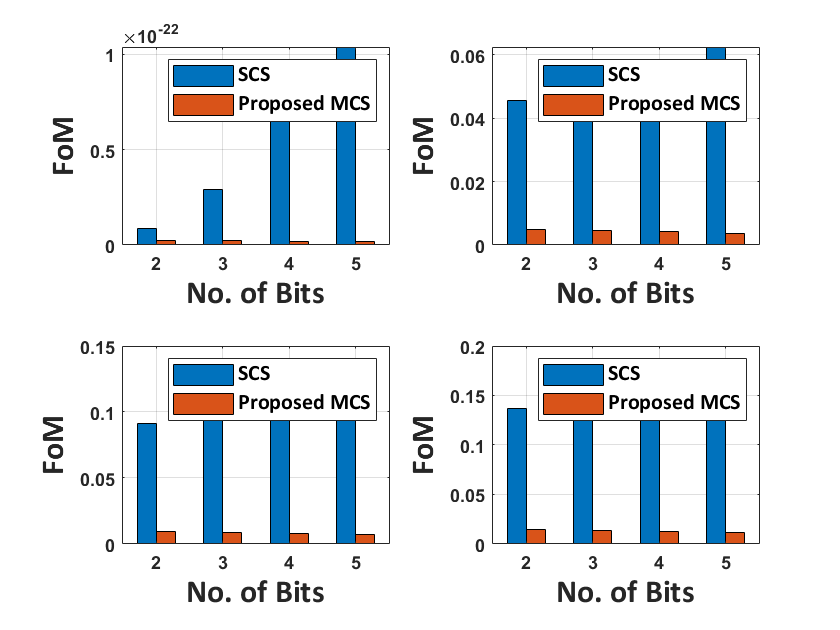

figure(3)
for iap=1:4
    subplot(220+iap)
    Bit=2:5;
    %  bar1(1:4,3) = reshape(FoM_de(iap,Bit,1),[4,1]);
    % bar1(1:4,7) = reshape(FoM_de(iap,Bit,2),[4,1]);
    %  bar1(1:4,2) = reshape(FoM_nm(iap,Bit,1),[4,1]);
    % bar1(1:4,6) = reshape(FoM_nm(iap,Bit,2),[4,1]);
    %bar1(1:4,1) = reshape(FoM_mc(iap,Bit,1),[4,1]);
    %bar1(1:4,3) = reshape(FoM_mc(iap,Bit,2),[4,1]);
    FoM_denm(1,4,1)=1/2*(FoM_denm(1,3,1)+FoM_denm(1,5,1));
    p = polyfit(Bit, reshape(FoM_denm(iap,Bit,1),[4,1])', 1); % 进行二次拟合，获取多项式系数
    yy_denm1 = polyval(p, Bit); % 计算拟合曲线的纵坐标
    bar1(1:4,2) = abs(yy_denm1);%reshape(FoM_denm(iap,Bit,1),[4,1]);
    p = polyfit(Bit, reshape(FoM_denm(iap,Bit,2),[4,1])', 1); % 进行二次拟合，获取多项式系数
    yy_denm2 = polyval(p, Bit); % 计算拟合曲线的纵坐标
    bar1(1:4,1) = abs(yy_denm2);%reshape(FoM_denm(iap,Bit,2),[4,1]);
    %bar1(1:4,3) = reshape(FoM_mc(iap,Bit,3),[4,1]);
    %bar1(1:10,3) = (loss_denm(1:4:40)');
    GO = bar(bar1,1,'EdgeColor','black');%边框颜色为黑色    
    %ylim([2000 3000])                              %y轴显示的范围，根据需要调整
    % 图例
    legend({'SCS','Proposed MCS'},'FontName','Calibri','fontsize',11);
    set(gca,'Xticklabel', Bit,'fontweight','bold')  %gca 坐标的句柄
    %set(gca,'xtick',0.2:0.04:0.6)
    xlabel('\fontname{Calibri}\fontsize{16}No. of Bits','FontWeight','bold')
    ylabel('\fontname{Calibri}\fontsize{16}FoM','FontWeight','bold')
    grid on
    set(gca, 'FontWeight', 'bold');
end
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'FoM_MCS2.pdf');